Part B
clear
% Define system parameters
a = 1;           % Nominal length (for normalization)
lambda = 1;      % Time constant factor
m0 = 1;          % Nominal mass
g = 9.81;        % Gravitational acceleration
         
b = 0;          % Given constant
c = 1;          % Given constant
L0 = 1;         % Nominal inductance (assumed value)

% Controller gains (you may need to tune these)
k1 = 30;         % Gain for position/velocity
k2 = 0.3;          % Sign control gain
k3 = 400;        % Gain for position control
k4 = 6;         % Gain for velocity control
gamma1 = 1;      % Gain for backstepping design
k_i = 100;         % Integral gain, reduced to avoid wind-up

% Define desired velocity (assumed to be zero for steady tracking)
x2_star = 0;     

% Define system dynamics (state-space model)
% State vector: x = [x1; x2] where x1 is position, x2 is velocity
f = @(x, u) [x(2); -b*x(2) + 1 + c*u];

% Backstepping controller with integral action
control_law = @(x, integral_error, x1_star) ...
    -k1*(x(2) + gamma1*x(1)) ...
    - k2*sign(x(2)) ...
    - k3*(x(1) - x1_star) ...
    - k4*x(2) ...
    - k_i * integral_error;

% Simulation setup
t_end = 40;         % Total time for simulation
dt = 0.01;         % Time step
time = 0:dt:t_end;  % Time vector
% Initialize control input and current storage
u_traj = zeros(length(time), 1);  % To store control input over time
i_traj = zeros(length(time), 1);  % To store current over time
% Initial conditions
x_init = [0; 0];    % Initial position and velocity
integral_error = 0; % Initialize the integral error

% Initialize state and reference trajectories
x_traj = zeros(length(time), 2);
x_traj(1,:) = x_init;
x1_ref = 0.05 + 0.01 * sin(time); % Reference position trajectory
%x2_ref = x2_star * ones(length(time), 1); % Reference velocity (constant)
x2_ref=0.01*cos(time)

x2_ref =     0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0099    0.0098    0.0098    0.0098    0.0098    0.0098    0.0097    0.0097    0.0097    0.0097    0.0096    0.0096    0.0096    0.0096    0.0095    0.0095    0.0095    0.0094    0.0094    0.0094    0.0093    0.0093    0.0092    0.0092    0.0092    0.0091    0.0091    0.0090    0.0090    0.0090    0.0089    0.0089    0.0088


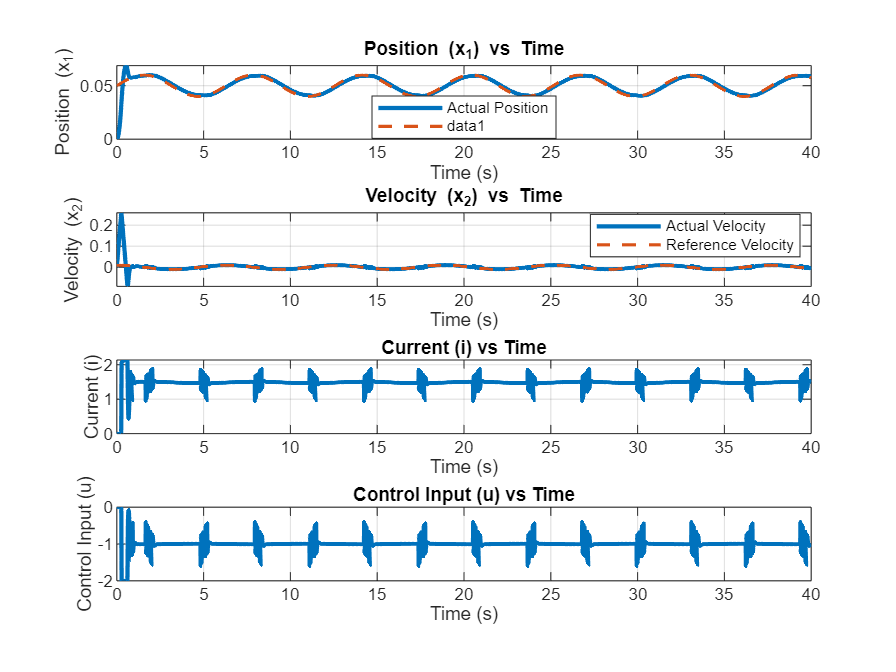

% Simulate the system
u_max = 0;         % Upper bound for control input
u_min = -2;        % Lower bound for control input

for t_idx = 2:length(time)
    % Get the current reference position at this time step
    x1_star = x1_ref(t_idx);

    % Get the current state
    x = x_traj(t_idx - 1, :)';  % Ensure x is a column vector

    % Update the integral of the position error
    error = x(1) - x1_star;
    integral_error = integral_error + error * dt;
    
    % Compute the control input using the backstepping law with integral action
    u = control_law(x, integral_error, x1_star);

    % Apply control input limits
    u = min(max(u, u_min), u_max);
    
    % Compute the current based on the force equation
    F = u; % Force is equal to the control input in this case
    i = sqrt(-2 * a * (1 + x(1)/a)^2 * F / L0);  % Compute current from force

    % Store the current
    i_traj(t_idx) = i;
    u_traj(t_idx) = u;
    % Compute the system dynamics (derivatives)
    dx = f(x, u);

    % Update the state using Euler integration
    x_traj(t_idx, :) = (x + dx * dt)';
end

% Plot results with reference
figure;

subplot(4,1,1);
plot(time, x_traj(:,1), 'LineWidth', 2, 'DisplayName', 'Actual Position');
hold on;
plot(time, x1_ref, '--', 'LineWidth', 1.5);
title('Position (x_1) vs Time');
xlabel('Time (s)');
ylabel('Position (x_1)');
legend('Location', 'Best');
grid on;

subplot(4,1,2);
plot(time, x_traj(:,2), 'LineWidth', 2, 'DisplayName', 'Actual Velocity');
hold on;
plot(time, x2_ref, '--', 'LineWidth', 1.5, 'DisplayName', 'Reference Velocity');
title('Velocity (x_2) vs Time');
xlabel('Time (s)');
ylabel('Velocity (x_2)');
legend('Location', 'Best');
grid on;

subplot(4,1,3);
plot(time, i_traj, 'LineWidth', 2, 'DisplayName', 'Current (i)');
title('Current (i) vs Time');
xlabel('Time (s)');
ylabel('Current (i)');
grid on;

subplot(4,1,4);
plot(time, u_traj, 'LineWidth', 2, 'DisplayName', 'Control Input (u)');
title('Control Input (u) vs Time');
xlabel('Time (s)');
ylabel('Control Input (u)');
grid on;

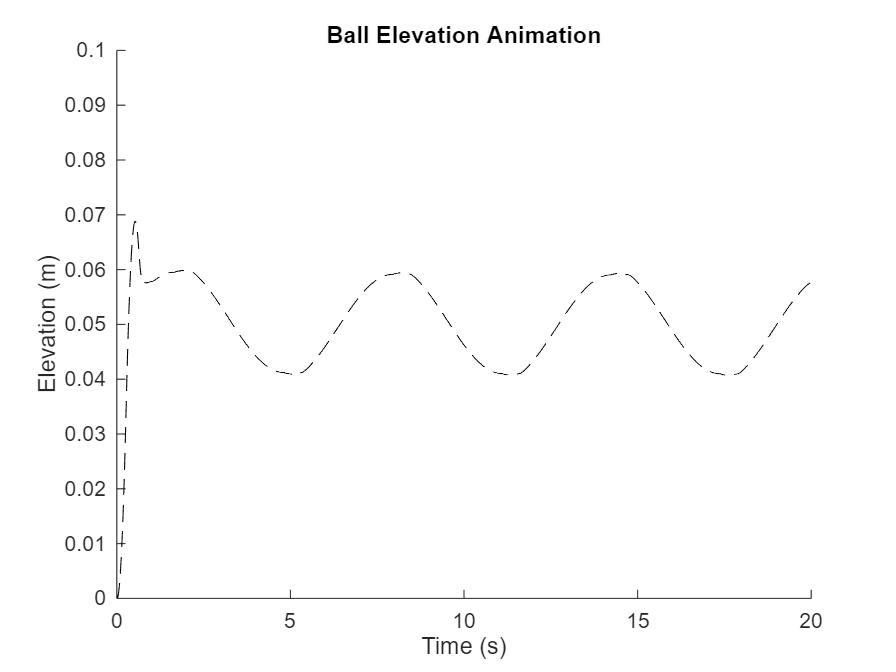


% Animation Setup
figure;
hold on;
xlabel('Time (s)');
ylabel('Elevation (m)');
title('Ball Elevation Animation');
ylim([0, 0.1]);         % Set vertical limits for ball position
xlim([0, 20]);          % Set horizontal limits for animation view
ball = plot(0, x_init(1), 'o', 'MarkerSize', 20, 'MarkerFaceColor', 'b');  % Ball plot
ball_path = plot(0, x_init(2), 'k--');  % Path of the ball (horizontal)


% Animation Loop (Horizontal and Vertical Movement)
for i = 1:length(time)
    % Update Ball Position
    set(ball, 'YData', x_traj(i, 1));  % Update the ball's vertical position (x1)
    set(ball, 'XData', time(i));        % Update the ball's horizontal position (t)
    
    % Update the ball path (trace of horizontal position)
    set(ball_path, 'XData', time(1:i));     % Update the horizontal position path
    set(ball_path, 'YData', x_traj(1:i, 1));  % Update the vertical position along the path
    
    % Pause to control animation speed (based on simulation time step)
    pause(10^-20);
end

hold off;

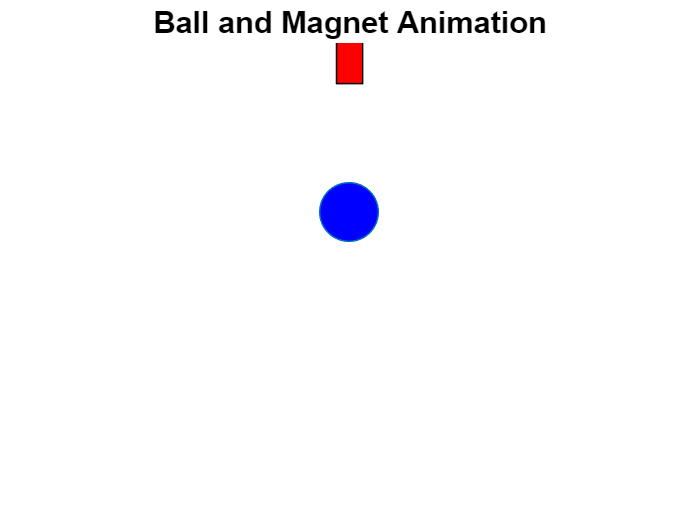

% Previous part of the simulation code (unchanged)

% Animation Setup for Ball and Magnet
figure;
hold on;
title('Ball and Magnet Animation');
ylim([0, 0.1]);  % Set vertical limits for ball position (adjust as needed)
xlim([-0.2, 0.2]);  % Set horizontal limits (magnet and ball don't move horizontally)

% Initializing Ball (Blue Circle) - Positioned to the right of the magnet
ball = plot(0, x_init(1), 'o', 'MarkerSize', 20, 'MarkerFaceColor', 'b');  

% Initializing Magnet (Red Rectangle) - Positioned below the ball on the Y-axis
magnet = rectangle('Position', [-0.01, 0.09, 0.02, 0.05], 'FaceColor', 'r');  % Magnet stays fixed below the ball

% Adjust the figure to make sure the magnet and ball appear
axis off; % Turn off the axis display
hold on;

% Animation Loop (Ball Moving Vertically)
skip = 5;  % Skip frames to speed up the animation
for i = 1:skip:length(time)
    % Update Ball Position (Ball on the right, vertical movement)
    set(ball, 'YData', x_traj(i, 1));  % Update the ball's vertical position (x1)
    
    % The magnet remains stationary below the ball
    % Magnet's Y position remains fixed (relative to ball's Y position)
    % No need to update magnet's Y position, it's fixed below the ball
    %set(magnet, 'Position', [-0.01, x_traj(i, 1)-0.05, 0.02, 0.05]);  % Magnet stays below the ball
    
    % Pause to control animation speed (based on simulation time step)
    pause(0.01);  % Adjust as needed for smooth animation
end

hold off;